# Estimate Model Parameters of a Symbolically Derived Plant Model in Simulink

This example uses [Simulink Design Optimization™](https://www.mathworks.com/products/sl-design-optimization.html) to estimate the unknown capacitance and initial voltage of a symbolically derived algebraic model of a simple resistor-capacitor (RC) circuit. The example solves the same problem and uses the same experimental data as [Estimate Model Parameters and Initial States](https://www.mathworks.com/help/sldo/ug/estimate-model-parameters-and-initial-states-code.html), but uses the closed-form solution for the RC circuit instead of the differential form.

This example uses Symbolic Math Toolbox™ capabilities to:

- Solve ordinary differential equations (ODE) using [`dsolve`](docid:symbolic_ug#bs220sw)

- Convert an analytical result into a Simulink block using [`matlabFunctionBlock`](docid:symbolic_ug#buvf4ru)

You perform design optimization to estimate the capacitance and initial voltage values of the analytical RC circuit. In particular, you match the experimental output voltage values with the simulated values.

## Solve Equation for RC Circuit

Define and solve the following differential equation for the RC circuit.

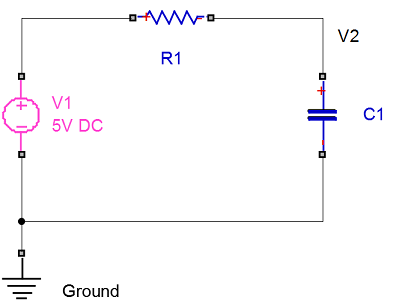

Here, `v2(t)` is the output voltage across capacitor `C1`, `v1` is the constant voltage across resistor `R1`, and `v20` is the initial voltage across the capacitor. Use `dsolve` to solve the equation.

syms C1 R1 v1 v20 real 
syms v2(t)
deq = (v1 - v2)/R1 - C1*diff(v2,t);
v2sol = dsolve(deq, v2(0) == v20)

Use `subs` to evaluate the solution for an `R1` value of 10 kOhm and `v1` value of 5 V.

v2sol = vpa(subs(v2sol,[R1,v1],[10e3,5]))

## Create Model with Block Representing RC Circuit

First, create a new Simulink model.

myModel = 'rcSymbolic';
new_system(myModel);
load_system(myModel);

Use `matlabFunctionBlock` to convert the symbolic result for the output voltage to a Simulink block representing the RC plant model. `matlabFunctionBlock` adds this new block to the model.

blockName = 'closedFormRC_block';
rcBlock = strcat(myModel,'/',blockName);
myVars = [C1,v20,t];
matlabFunctionBlock(rcBlock,v2sol,...
    'vars',myVars,...
    'functionName','myRC',...
    'outputs',{'v2'});

## Add More Blocks

Add and arrange other blocks with positions and sizes relative to the RC block.

rcBlockPosition = get_param(rcBlock,'position');
rcBlockWidth = rcBlockPosition(3)-rcBlockPosition(1);
rcBlockHeight = rcBlockPosition(4)-rcBlockPosition(2);
constantBlock = 'built-in/Constant';
timeBlock = 'simulink/Sources/Ramp';
outputBlock = 'built-in/Outport';

`C1` and `v20` are the parameters to estimate. First, introduce and initialize these parameters in the MATLAB workspace, using the initial values of 460 $\rm \mu F$ and 1 V, respectively. Then create constant blocks for both parameters.

C1val = 460e-6;
v20val = 1.0;
posX = rcBlockPosition(1)-rcBlockWidth*2;
posY = rcBlockPosition(2)-rcBlockHeight*3/4;
pos = [posX,posY,posX+rcBlockWidth/2,posY+rcBlockHeight/2];
add_block(constantBlock,strcat(myModel,'/C1'),'Value','C1val',...
    'Position',pos);
pos = pos + [0 rcBlockHeight 0 rcBlockHeight];
add_block(constantBlock,strcat(myModel,'/v20'),'Value','v20val',...
    'Position',pos);

Add a ramp for time.

pos = pos + [0 rcBlockHeight 0 rcBlockHeight];
add_block(timeBlock,strcat(myModel,'/t'),'Slope','1','Position',pos);

Add an output port.

pos = [rcBlockPosition(1)+2*rcBlockWidth,...
    rcBlockPosition(2)+rcBlockHeight/4,...
    rcBlockPosition(1)+2*rcBlockWidth+rcBlockWidth/2,...
    rcBlockPosition(2)+rcBlockHeight/4+rcBlockHeight/2];
add_block(outputBlock,strcat(myModel,'/v2'),'Port','1','Position',pos);

Now, wire blocks in the model. The model is ready for Simulink Design Optimization.

myAddLine = @(k) add_line(myModel,...
    strcat(char(myVars(k)),'/1'),...
    strcat(blockName,'/',num2str(k)),...
    'autorouting','on');
arrayfun(myAddLine,(1:numel(myVars)));
add_line(myModel,strcat(blockName,'/1'),'v2/1','autorouting','on');
open_system(myModel);

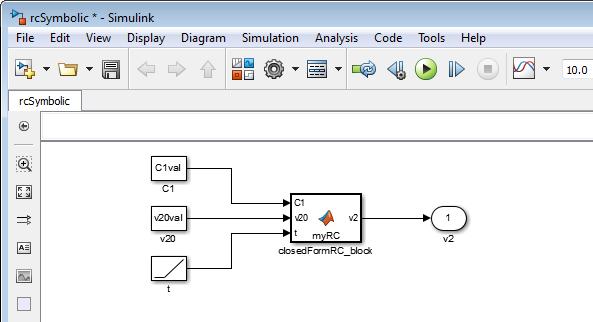

## Estimate Parameters

Get the measured data.

load sdoRCCircuit_ExperimentData

The variables `time` and `data` are loaded into the workspace. `data` is the measured capacitor voltage for times `time`.

Create an `sdo.Experiment` object to store the experimental voltage data.

Exp = sdo.Experiment(myModel);

Create an object to store the measured capacitor voltage output.

Voltage = Simulink.SimulationData.Signal;
Voltage.Name      = 'Voltage';
Voltage.BlockPath = rcBlock;
Voltage.PortType  = 'outport';
Voltage.PortIndex = 1;
Voltage.Values    = timeseries(data,time);

Add the measured capacitor data to the experiment as the expected output data.

Exp.OutputData = Voltage;

Get the parameters. Set a minimum value for `C1`. Note that you already specified the initial guesses.

c1param = sdo.getParameterFromModel(myModel,'C1val');
c1param.Minimum = 0;
v20param = sdo.getParameterFromModel(myModel,'v20val');

Define the objective function for estimation. The code for `sdoRCSymbolic_Objective` used in this example is given in the Helper Functions section at the end of the example.

estFcn = @(v) sdoRCSymbolic_Objective(v,Exp,myModel);

Collect the model parameters to be estimated.

v = [c1param;v20param];

Because the model is entirely algebraic, turn off warning messages that instruct you to select a discrete solver.

set_param(myModel,'SolverPrmCheckMsg','none');

Estimate the parameters.

opt = sdo.OptimizeOptions;
opt.Method = 'lsqnonlin';
vOpt = sdo.optimize(estFcn,v,opt);

Show the estimated values.

fprintf('C1 = %e v20 = %e\n',vOpt(1).Value, vOpt(2).Value);

## Compare Simulated and Experimental Data

Update the experiment with the estimated capacitance and capacitor initial voltage values.

Exp = setEstimatedValues(Exp,vOpt);

Simulate the model with the estimated parameter values and compare the simulated output with the experimental data.

Simulator = createSimulator(Exp);
Simulator = sim(Simulator);
SimLog    = find(Simulator.LoggedData,get_param(myModel,'SignalLoggingName'));
Voltage   = find(SimLog,'Voltage');
plot(time,data,'ro',Voltage.Values.Time,Voltage.Values.Data,'b')
title('Simulated and Measured Responses')
legend('Measured Voltage','Simulated Voltage','Location','Best')
close_system(myModel,0);

## Helper Functions

function vals = sdoRCSymbolic_Objective(v,Exp,myModel) 
    r = sdo.requirements.SignalTracking;
    r.Type      = '==';
    r.Method    = 'Residuals';
    r.Normalize = 'off';
    Exp  = setEstimatedValues(Exp,v);
    Simulator = createSimulator(Exp);
    Simulator = sim(Simulator);
    SimLog  = find(Simulator.LoggedData,get_param(myModel,'SignalLoggingName'));
    Voltage = find(SimLog,'Voltage');
    VoltageError = evalRequirement(r,Voltage.Values,Exp.OutputData(1).Values);
    vals.F = VoltageError(:);
end

*Copyright 2019 The MathWorks, Inc.*